# Preprocessing 1: Loading and Saving Data

In this livescript, we will go over loading and saving EEG datasets. More specifically, we will learn about functions to load in Lab Streaming Layer Recordings and saving them as set files that are easier to load. As you have noticed, this is only part of the preprocessing pipeline (See below). At the end, we will write a preprocessing function (which you can modify for any research purpose) that we can use to batch process multiple EEG datasets. You can view the following YouTube playlist on this preprocessing pipeline using this [**link**](https://youtube.com/playlist?list=PLXc9qfVbMMN1ZS3sU2xT2hhfB5PAmuNae). 

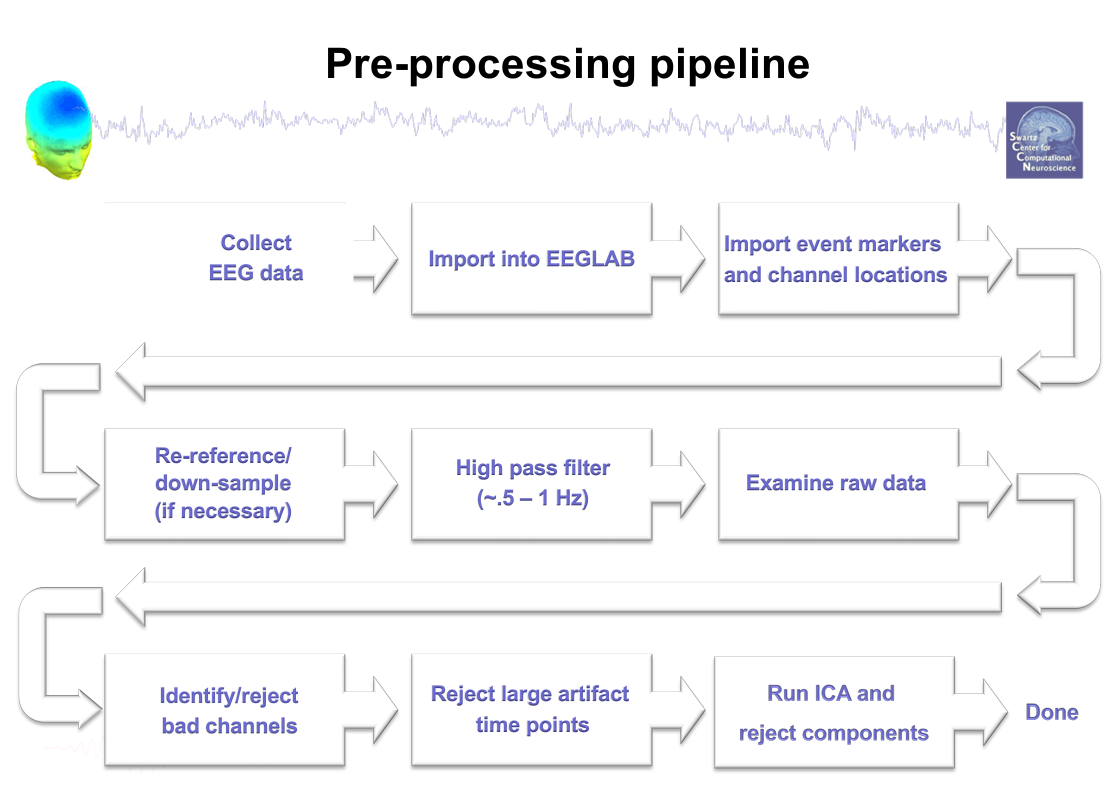

## Loading Data

### Naming Convention

Before even starting to load the data, it is important to know where your data is located. Are they named in a consistent manner in which you can batch process them? One important aspect in recording data that can be often overlooked is how the recordings are named. Consistency is key because with programming you can load in files with ease. For instance, the dataset we will use has the following naming scheme: 

**vrcct_SUBJECT_STUDY_PART.xdf**

Each recording has a **SUBJECT **identifier (or participant identifier) like **p4 **or **p16**. Each recording is from the subject's first or second session of the experiment. The **STUDY** part of our naming scheme describes this: a dataset from the first session will have **prestudy** and a dataset from the second session will have **poststudy**. Within each session, the experiment is broken up into three parts that our **PART** represents: **prebaseline**, **condition**, and **postbaseline**. The baseline parts indicate baseline measurements when the subject just sat there before and after the experiment. The condition part indicates the part of the session where subject undergoes guided meditation.

How would we write MATLAB code to define paths to our datsets?

One useful function is **fullfile **that builds a file specification from the specified folder or file names regardless of what operating system you are using (MacOS or Windows). Here is the [**documentation**](https://www.mathworks.com/help/matlab/ref/fullfile.html). It takes in multiple [**character vectors**](https://www.mathworks.com/help/matlab/ref/char.html) (e.g. 'data' or 'MATLAB') and returns a character vector of the full path of the folder or file you are interested in. It is useful because file separator characters are different between MacOS and Windows: Windows use backslash (\) while MacOS uses forward slash (/). It's a way to make the code adaptable to any operating system.

% Example of where our LSL recordings may be located: 
%Change the first input to the folder path where your data are
dir_data = 'data';
dir_xdf = fullfile(dir_data,'xdf');

%Displaying our data path:
fprintf("Our LSL recordings are located in '%s'",dir_xdf)

Another important function is **sprintf **that formats data into string or character vectors. Here is the [**documentation**](https://www.mathworks.com/help/matlab/ref/sprintf.html). Its first argument is the format specifier with formatting operators (e.g. %s for string/character vector or %f for a float). The rest of the arguments (the number of additional arguments must equal to the number of formatting operators you used in the format specifier) will fill in all formatting operators. Let's look at some examples: 

%Format specifier for our recording: 
file_spec = 'vrcct_%s_%s_%s.%s'; %Four char formatting operators

%Let us define the name parts of our file: 
sub = 'p16'; %subject or participant 16
study = 'prestudy'; %First session of experiment
part = 'condition'; %meditation part of session
ext = 'xdf'; %File extension of our dataset (LSL recording)

%Let us use sprintf to define a dataset name: 
file_name = sprintf( ...
    file_spec, ...
    sub,study,part,ext);

%Additionally, we can use fullfile to get the full path of
% this dataset: 
file_path = fullfile(dir_xdf,file_name);

%Displaying our results with fprintf:
fprintf("Our dataset file name is '%s'",file_name);
fprintf("The full path to our dataset file is '%s'",file_path);

Addtionally, we can use some MATLAB functions to make folders and check if a file exists. The functions [**isfolder**](https://www.mathworks.com/help/matlab/ref/isfolder.html) or [**isfile**](https://www.mathworks.com/help/matlab/ref/isfile.html) checks if the path to a folder or file respectively is located there. These functions take in a path (character vector) as an input. The output is a 0 if the specified folder or file is not present. The output is 1 if the specified folder of file is present. It's an easy way to check if a file/folder actually exists. The [**mkdir**](https://www.mathworks.com/help/matlab/ref/mkdir.html) function creates the folder specified by the input character vector path. Let's look at some example: 

% Define a path to a new folder where we will store our saved files
dir_set = fullfile(dir_data,'set');

%Using an if/else statement to check if folder already exists: 
if not(isfolder(dir_set))
    fprintf('Creating a new folder at %s',dir_set);
    mkdir(dir_set); % if the folder doesn't exist, we will create it
    disp('Done!')
else
    fprintf('%s already exists!',dir_set)
end

%Check with your file explorer or finder to see that the new folder has
% been created! 

While it may not be obvious now, these consistent naming convention and functions can be useful in batch processing files using a for loop. We will go over what I mean in a later tutorial. 

### Loading in LSL Recordings using pop_loadxdf

Before we start loading LSL recordings, we have specifiy where are files are and where we will save our files. The next code block will be used over and over again in future tutorials. I personally reuse/modify it in different projects, so feel free to use/modify it. 

%Directory where are data are located: 
dir_data = 'data'; %Change this to where your data is

%Directory where our LSL recordings are located: 
dir_xdf = fullfile(dir_data,'xdf');

%Directory where headset data are located: 
dir_head = fullfile(dir_data,'headset_channel_locations');

%Directory where we will save our data: 
dir_set = fullfile(dir_data,'set');

%Using an if/else statement to check if folder already exists: 
if not(isfolder(dir_set))
    fprintf('Creating a new folder at %s',dir_set);
    mkdir(dir_set); % if the folder doesn't exist, we will create it
    disp('Done!')
else
    fprintf('%s already exists!',dir_set)
end

We will also define our format specifier to load our data (this will change depending on how your data is named): 

%File Specifier to easily load in files
file_spec = 'vrcct_%s_%s_%s.%s';

% Formatting our specifier for a specific lsl recording
sub = 'p16';
study = 'prestudy';
part = 'condition';
ext = 'xdf';
file_name = sprintf( ...
    file_spec, ...
    sub, study, part, ext);

Next, we can initialize eeglab and use [**pop_loadxdf**](https://github.com/xdf-modules/xdf-EEGLAB/blob/master/pop_loadxdf.m). This function requires one input path to your LSL recording. It has optional inputs: streamname, streamtype, and exclude_markerstreams. You can look at the documentations to get more information on these optional inputs. For the most part, we usually just use the required input (path to LSL recording). 

% Change this to the path where eeglab folder is
%eeglab_path = fullfile(matlabroot,'toolbox','eeglab');
%addpath(genpath(eeglab_path));

%Initializing EEGlab
eeglab;

%Loading LSL recording: 
EEG = pop_loadxdf( ...
    fullfile(dir_xdf,file_name));

Loading data is pretty self explanatory, but what do we get from this? It's an EEG struct, and we went over it briefly in the last tutorial. 

## The EEG struct

We loaded in our data. What is EEG? As said earlier, it is a struct with a lot of relevant data about this recording. Please review the last tutorial for more information on structs. What information do we have here?

%% We can access the dataset's file name and path
fprintf('EEG.filename: %s',EEG.filename);
fprintf('EEG.filepath: %s',EEG.filepath);

%Additionally, we can assign subject identifier if it is not present
% (it is an empty field by default and it is optional)
EEG.subject = sub; 
fprintf('EEG.subject: %s',EEG.subject);

%There is also a field for the number of channels: 
fprintf('EEG.nbchan: %i',EEG.nbchan);

%You can access the number of data points in dataset:
fprintf('EEG.pnts: %i',EEG.pnts);

%The sampling rate of the dataset can be accessed:
fprintf('EEG.srate: %i',EEG.srate);

%The first and last timestamps can also be accessed
fprintf('EEG.xmin: %0.1f',EEG.xmin); %seconds
fprintf('EEG.xmax: %0.1f',EEG.xmax); %seconds

% Timestamps can also be accessed in milliseconds;
% It is a row vector containing all time stamps
timestamps = EEG.times/1000; 
fprintf( ...
    'The timestamp variable has %i rows and %i columns', ...
    size(timestamps,1),size(timestamps,2));

%Data can be accessed using the data field
% it has m rows (number of channels), n columns (number of data points), 
% and possibly p slices (number of trials/epochs). 

%There are also channel information (which is a struct): 
disp(EEG.chaninfo);

%Channel locations, labels, coordinates, etc, are also accessible (struct):
disp(EEG.chanlocs)

%Event markers are also stored (if any) as a struct
% type indicates the event (e.g. 'start_meditation audio')
% latency is the sample number when the event occurred
% duration is the duration (number of samples) the event lasted
disp(EEG.event);

%You also have other metadata (struct)
% You can explore these fields if you want, but we don't use it often
disp(EEG.etc);

## Saving EEG as set Files

Sometimes loading LSL recordings take a long time. It might be because of the amount of data or a large number of event markers. To save time, it is often better to save your dataset as set files as they are light in storage space and can be loaded faster. The two functions we use is pop_saveset and pop_loadset to save and load EEG data, respectively. 

**pop_saveset** has multiple inputs: the EEG struct, filename, filepath and savemode. The first three are self explanatory. The save mode is we use is 'twofiles' and not only does it save a set file, but also an fdt file containing binary information. The reason is because some EEGLAB functions may require this fdt file (I encountered it trying to use AMICA). The output is the saved dataset. 

**pop_loadset** has multiple inputs: filename and filepath. These are pretty self explanatory. 

Let's save our data: 

% We change the extension for our file name to 'set'
ext = 'set';
file_name = sprintf( ...
    file_spec, ...
    sub,study,part,ext);

%Saving our dataset: 
EEG = pop_saveset( ...
    EEG, ...
    'filename',file_name, ...
    'filepath',dir_set, ... %notice that we save in dir_set
    'savemode','twofiles');

%Check with your file explorer or finder to see that the EEG dataset has
%been saved! 

Let's load in the data into a new variable

EEG_loaded = pop_loadset( ...
    'filename',file_name, ...
    'filepath',dir_set);

## Conclusion

In this tutorial, we have learned functions that will help us load and save EEG data. The names of our files allow us to easily do this. This information will be used in subsequent tutorials, so please try to get acquianted with these functions and skills. Next, we will import channel information and downsample our data. 